
clear;
clc;
format long;
disp(strcat("report Generated on: ",string(datestr(now))))

report Generated on: 14-Apr-2023 05:58:43




SingleAnalysis = false;

### **Clean Everything Before Start**



% Check if running in batch mode
tempMatPath = fullfile(pwd, 'temp.mat');
if exist(tempMatPath, 'file')
    if (SingleAnalysis==true)
    delete(tempMatPath);
    batchMode = false;
    else
    % Load variables from the temporary MAT-file (batch mode)
    load(tempMatPath, 'batchMode', 'bi', 'dirNames', 'dirPaths', 'dirTest', 'dirPath', 'allDataFolderPath', 'scriptPath');
    end
else
    % Set variables for standalone mode (You can customize this part as needed)
    batchMode = false;
    % Define or load the necessary variables when running in standalone mode
    % For example, you can set dirTest, dirPath, etc. according to your needs
%     dirTest = 'YourStandAloneDirTest';
%     dirPath = 'YourStandAloneDirPath';
end



%for Scalogram Analysis
step_window = 10;
window = 30;
 excGradTreshhold = 0.05;

### **Select the Specific Log Folder**

The folder Contains 5 files

- PreFlight CAT Test Image

- PreFlight CAT Test CSV

- PostFlight CAT Test Image

- PostFlight CAT Test CSV

- Trial Data .mat File

%select directory
 if ~exist('dirPath','var')
dirPath = uigetdir("logs\firstSeries\","Select the Log Directory...");
else 
   % dirPath = dirTest;
 end
 
listFiles = dir(dirPath);
fileNames = {listFiles.name};
% create a logical index of files that are not hidden and not directories
validFiles = ~ismember(fileNames,{'.','..'}) & ~[listFiles.isdir] & ~strncmp('.',fileNames,1);
fileNames = fileNames(validFiles);


preReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_pre.csv")));
preReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_pre.jp")));

postReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_post.csv")));
postReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_post.jp")));

matFile = fullfile(dirPath,fileNames(contains(fileNames,".mat")));

%main mat file

load(string(matFile));


%Print Info for the test details
disp("Test Directory");

Test Directory


disp(dirPath);

C:\Users\Alireza\MATLAB Drive\FatigueThesis\logs\firstSeries\Alireza Ghaderi_10-04-2023_04-59-05



disp("Pilot Info");

Pilot Info


disp(pilot);

           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 384
         endPVT: 382
     hoursAwake: 2
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [47881×22 table]
    description: {''}
           time: "10-Apr-2023 04:59:05"
        caffein: 'None'



pilot_raw = pilot;

%load preflight CAT Test

preFlightCAT = catImportFun(string(preReportcsv));
disp("Before Test CAT");

Before Test CAT


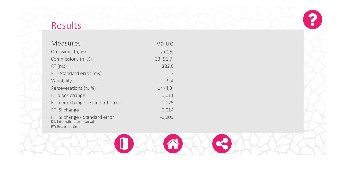

imshow(string(preReportimg));


%load postflight CAT Test

postFlightCAT = catImportFun(string(postReportcsv));
disp("After Test CAT");

After Test CAT


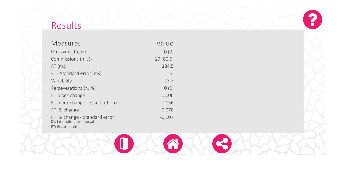

imshow(string(postReportimg));

### **Data Preprocess**

desireFs = 30;
lowPassCutoff_pos = 2;
clipRate_pos = 99.990;
detrendingSmoothingFactor_pos = 0.05;
median_filter_window_pos = 10;
smoothingWindow_pos = 30; %moving average window

lowPassCutoff_vel = 4;
clipRate_vel = 99;
detrendingSmoothingFactor_vel = 0.1;
median_filter_window_vel = 30;
smoothingWindow_vel = 30; %moving average window
stationaryThresholdFactor_vel = 0.25;

%-------------------------------------------------------------------------

%remove non unique time from data
[C,ia] = unique(pilot.data.time(:,1),'rows');
startPadding = 100;
endPadding = 30;
ia = ia(startPadding:end-endPadding);
data = pilot.data;
data(2:height(data),:) = []

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator      throttle       rudder         roll       pitch         hdev         vdev       dmeNM        ias       altitude      vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ___________    _________    ___________    ________    _______

for col = 1 : width(pilot.data)
    temp = pilot.data(ia,col);
    data(1:height(temp),col) = temp;
end


%resampling
data = signalResample(data,desireFs);


Iris Preprocessing

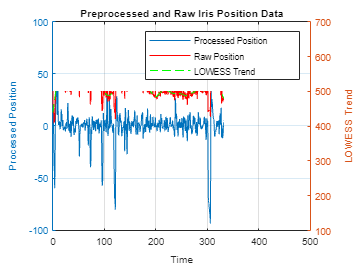

%iris position
time = double(data.time);
irisX_raw = data.irisx;
irisY_raw = data.irisy;


% Preprocess the iris data
[processed_position, position_detrended]  = preprocess_iris_data(irisX_raw, irisY_raw, time, clipRate_pos, lowPassCutoff_pos, smoothingWindow_pos,detrendingSmoothingFactor_pos,median_filter_window_pos);

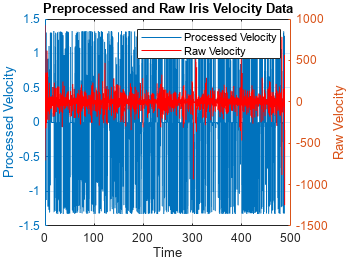


%iris velocity
%preprocess and initilaize iris velocity

processed_velocity = preprocess_iris_velocity(time, position_detrended,clipRate_vel, median_filter_window_vel, lowPassCutoff_vel, smoothingWindow_vel, detrendingSmoothingFactor_vel,stationaryThresholdFactor_vel);

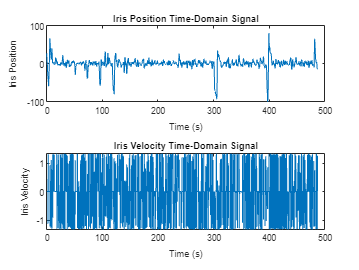

Feature values for a single trial:

Iris Position:
mean: -0.0000
std: 15.5353
skewness: -2.2164
kurtosis: 16.5669
rms: 15.5348
crestFactor: 5.1973
shapeFactor: 1.9120
impulseFactor: 12.3590
zeroCrossingRate: 0.0166
autocorrelation: 0.0000
avgPeakAmplitude: 7.4581
avgTimeToZero: 2.3337
numPeaks: 207.0000
spectralCentroid: 0.0929
spectralBandwidth: 0.0977
spectralContrast: 3074082887218.2310
waveletFeatures.energy: 207717.3620
waveletFeatures.entropy: -299576398.8019
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.stdCoeff: 2.6831

Iris Velocity:
mean: -0.0080
std: 0.5312
skewness: -0.0249
kurtosis: 4.2985
rms: 0.5312
crestFactor: 2.4963
shapeFactor: 1.8005
impulseFactor: 4.4946
zeroCrossingRate: 0.0202
autocorrelation: 3.2785
avgPeakAmplitude: 0.5867
avgTimeToZero: 0.8257
numPeaks: 590.0000
spectralCentroid: 0.9372
spectralBandwidth: 1.3921
spectralContrast: 13648.0919
waveletFeatures.energy: 247.7395
waveletFeatures.entropy: -160804.0942
waveletFeatures.meanCoeff: -0.0000
waveletFeat

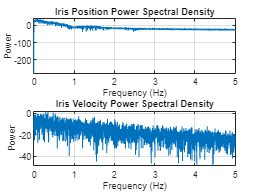

%feature Extraction

positionFeatures = computeIrisFeatures(processed_position, time, desireFs);
velocityFeatures = computeIrisFeatures(processed_velocity, time, desireFs);


%plot Features
plotIrisFeatures(processed_position, processed_velocity, time, desireFs, 5);

### Finding Fixations by Position

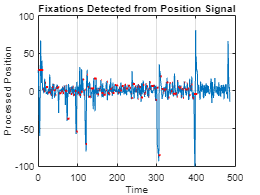

min_duration_pos = 0.7; % Minimum duration of fixations in seconds
merge_threshold_pos = 0.4; % Threshold for merging close peaks in seconds
trigger_change_threshold = 0.3; % Threshold to detect trigger changes in the position data
[num_fixations_pos, fixation_durations_pos, fixation_amplitudes_pos] = find_fixations_position(time, processed_position, min_duration_pos, merge_threshold_pos, trigger_change_threshold);

### Finding Fixations by Velocity

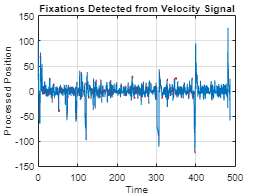

min_duration_vel = 0.7; % Minimum duration of fixations in seconds
velocity_threshold= 0.1; % Threshold for merging close peaks in seconds
merge_threshold_vel = 1;
[num_fixations_vel, fixation_durations_vel, fixation_amplitudes_vel] = find_fixations_velocity(time, position_detrended, processed_velocity,min_duration_vel, velocity_threshold,merge_threshold_vel);



%fixation analysis



## Averaging and Displaying Iris Data


%Display Iris Results
%since the values obtained by velocity and position are diffent and yet
%Ihave no idea which one is better, right now I am averaging the two as a
%better measure.



%irisResult Exceedance
irisResult.processed_position = processed_position;
irisResult.processed_velocity = processed_velocity;
irisResult.processed_irisX_raw = irisX_raw;
irisResult.processed_irisY_raw = irisY_raw;
irisResult.relative_irisX_raw = data.dxIris;
irisResult.relative_irisX_raw =  data.dyIris;
irisResult.meanFixationDurationByPosition = mean(fixation_durations_pos);
irisResult.stdFixationDurationByPosition = std(fixation_durations_pos);
irisResult.numFixationByPosition = num_fixations_pos;
irisResult.meanFixationAmplitudeByPosition = mean(fixation_amplitudes_pos);
irisResult.stdFixationAmplitudeByPosition = std(fixation_amplitudes_pos);
irisResult.meanFixationDurationByVelocity = mean(fixation_durations_vel);
irisResult.stdFixationDurationByVelocity = std(fixation_durations_vel);
irisResult.numFixationByVelocity = num_fixations_vel;
irisResult.meanFixationAmplitudeByVelocity = mean(abs(fixation_amplitudes_vel));
irisResult.stdFixationAmplitudeByVelocity = std(fixation_amplitudes_vel);
irisResult.meanFixationDuration = mean([irisResult.meanFixationDurationByVelocity , irisResult.meanFixationDurationByPosition]);
irisResult.stdFixationDuration = std([irisResult.meanFixationDurationByVelocity , irisResult.meanFixationDurationByPosition]);
irisResult.numFixation = mean([num_fixations_vel , num_fixations_pos]);
irisResult.meanFixationAmplitudeByVelocity = mean(abs(fixation_amplitudes_vel));
irisResult.stdFixationAmplitudeByVelocity = std(fixation_amplitudes_vel);
irisResult.positionFeatures = positionFeatures;
irisResult.velocityFeatures = velocityFeatures;
disp(irisResult);


%if ~SingleAnalysis

                 processed_position: [14610×1 double]
                 processed_velocity: [14610×1 double]
                processed_irisX_raw: [14610×1 double]
                processed_irisY_raw: [14610×1 double]
                 relative_irisX_raw: [14610×1 double]
     meanFixationDurationByPosition: 2.392409240924092
      stdFixationDurationByPosition: 1.690639407814469
              numFixationByPosition: 202
    meanFixationAmplitudeByPosition: -0.205567292412652
     stdFixationAmplitudeByPosition: 17.018465588287111
     meanFixationDurationByVelocity: 1.419020715630886
      stdFixationDurationByVelocity: 0.673344243234250
              numFixationByVelocity: 177
    meanFixationAmplitudeByVelocity: 23.117869111767799
     stdFixationAmplitudeByVelocity: 34.565170839058844
               meanFixationDuration: 1.905714978277489
                stdFixationDuration: 0.688289626963999
                        numFixation: 1.895000000000000e+02
                   positionFeatures

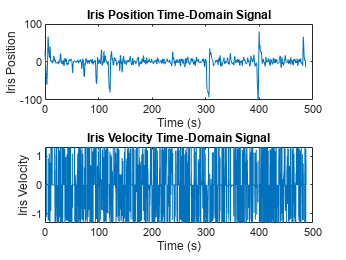

Feature values for a single trial:

Iris Position:
mean: -0.0000
std: 15.5353
skewness: -2.2164
kurtosis: 16.5669
rms: 15.5348
crestFactor: 5.1973
shapeFactor: 1.9120
impulseFactor: 12.3590
zeroCrossingRate: 0.0166
autocorrelation: 0.0000
avgPeakAmplitude: 7.4581
avgTimeToZero: 2.3337
numPeaks: 207.0000
spectralCentroid: 0.0929
spectralBandwidth: 0.0977
spectralContrast: 3074082887218.2310
waveletFeatures.energy: 207717.3620
waveletFeatures.entropy: -299576398.8019
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.stdCoeff: 2.6831

Iris Velocity:
mean: -0.0080
std: 0.5312
skewness: -0.0249
kurtosis: 4.2985
rms: 0.5312
crestFactor: 2.4963
shapeFactor: 1.8005
impulseFactor: 4.4946
zeroCrossingRate: 0.0202
autocorrelation: 3.2785
avgPeakAmplitude: 0.5867
avgTimeToZero: 0.8257
numPeaks: 590.0000
spectralCentroid: 0.9372
spectralBandwidth: 1.3921
spectralContrast: 13648.0919
waveletFeatures.energy: 247.7395
waveletFeatures.entropy: -160804.0942
waveletFeatures.meanCoeff: -0.0000
waveletFeat


plotIrisFeatures(processed_position, processed_velocity, time, desireFs, 5);

%Creating Figures
nBinsPlots = 400;

[processed_irisX, processed_irisY] = preprocess_iris_data_separate(irisX_raw, irisY_raw, time, clipRate_pos, lowPassCutoff_pos, smoothingWindow_pos, detrendingSmoothingFactor_pos, median_filter_window_pos);
disp(" With Processed Data");
plot_scan_pattern_visualizations(processed_irisX, processed_irisY, processed_velocity, time, nBinsPlots);

disp(" With Raw Data");

 With Processed Data


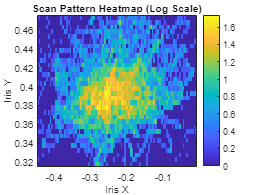

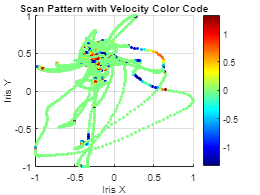

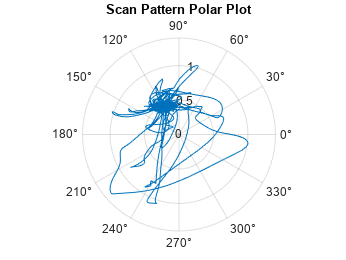

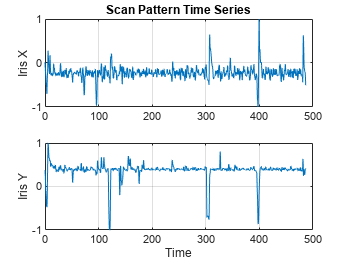

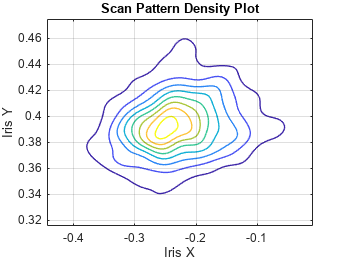

plot_scan_pattern_visualizations(irisX_raw, irisY_raw, processed_velocity, time, nBinsPlots);

%end

 With Raw Data


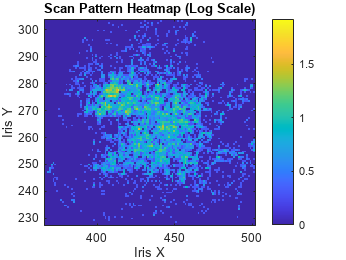

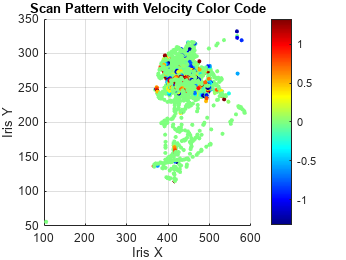

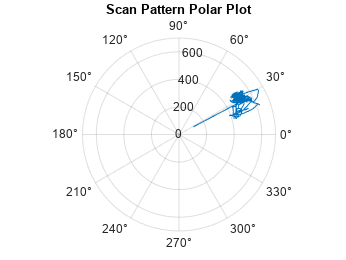

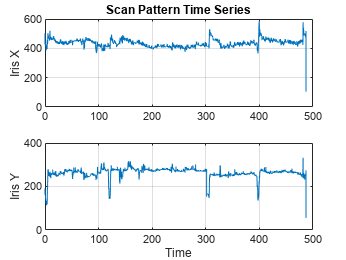

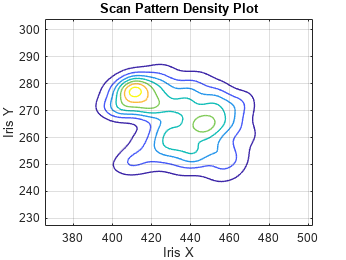

### Exceedance Data Analysis

%exceedance

refIas = 90;


 hdev = data.hdev;
 vdev = data.vdev;
 iasdev = (data.ias - refIas); 
DME = data.dmeNM;
exceedanceGradientLowpassCutoff = 2;

exceedance = exceedance_analysis(hdev, vdev, iasdev, DME, time, desireFs,exceedanceGradientLowpassCutoff);
% Find exceeding peaks in rateExceedance
    Exceeding_Treshhold = 0.05;
    exceeeding_min_duration = 2;
    exceedance_merge_time = 2;
[startTimes, durations, amplitudes] = findExceedingPeaks(exceedance.rateExceedance, ...
    time, Exceeding_Treshhold, exceeeding_min_duration, exceedance_merge_time);
    exceedance.exceedingStartTimes = startTimes;
    exceedance.exceedingDurations = durations;
    exceedance.exceedingAmplitudes =amplitudes;


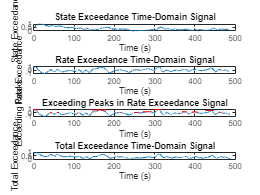

Feature values for a single trial:

State Exceedance:
mean: 0.3131
std: 0.2343
skewness: 1.1415
kurtosis: 3.6872
rms: 0.3911
crestFactor: 2.5571
shapeFactor: 1.2491
impulseFactor: 3.1940
zeroCrossingRate: 0.0001
autocorrelation: 9364.0458
avgPeakAmplitude: 0.2640
avgTimeToZero: 11.9573
numPeaks: 40.0000
spectralCentroid: 0.0388
spectralBandwidth: 0.0446
spectralContrast: 18802214573.5527
waveletFeatures.energy: 8.6072
waveletFeatures.entropy: -3331.1019
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.stdCoeff: 0.0137

Rate Exceedance:
mean: 0.2807
std: 0.2768
skewness: 1.1150
kurtosis: 3.0390
rms: 0.3942
crestFactor: 2.5367
shapeFactor: 1.4042
impulseFactor: 3.5622
zeroCrossingRate: 0.0000
autocorrelation: 3180.1579
avgPeakAmplitude: 0.3002
avgTimeToZero: 10.6877
numPeaks: 20.0000
spectralCentroid: 0.0409
spectralBandwidth: 0.0464
spectralContrast: 443487107.0915
waveletFeatures.energy: 25.2263
waveletFeatures.entropy: -11606.3394
waveletFeatures.meanCoeff: -0.0000
waveletFeatures.st

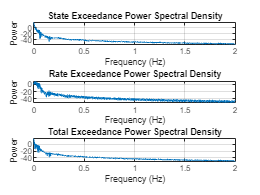


%display the features for exceedance in plots
maxFreqInChart = 2;
plotExceedanceFeatures(exceedance, time, desireFs,maxFreqInChart);

### Average the post and pre CAT results:

% Create an empty struct for the average data
avgCAT = struct();
beforeCAT = preFlightCAT;
afterCAT = postFlightCAT;
% Loop through each struct in the beforeCAT array
for i = 1:length(beforeCAT)
    % Loop through each field in the struct
    fields = fieldnames(beforeCAT(i));
    for j = 1:length(fields)
        % Skip the 'blocks' field
        if strcmp(fields{j},'blocks')
            continue
        end
        % If the field is a scalar or a string, copy it directly to the
        % avgCAT struct`
        if isscalar(beforeCAT(i).(fields{j})) || ischar(beforeCAT(i).(fields{j}))
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        % If the field is a struct, loop through its fields and average each one
        elseif isstruct(beforeCAT(i).(fields{j}))
            subfields = fieldnames(beforeCAT(i).(fields{j}));
            substruct = struct();
            for k = 1:length(subfields)
                bef = beforeCAT(i).(fields{j}).(subfields{k});
                aft = afterCAT(i).(fields{j}).(subfields{k});
                substruct.(subfields{k}) = (bef+aft)/2 ;
            end
            avgCAT(i).(fields{j}) = substruct;
        % Otherwise, assume the field is an array and average its values element-wise
        else
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        end
    end
end

### Output Object Data

%output object definiton
pilot.data = data;
output.trial = pilot;
output.trial_raw = pilot_raw;
output.preFlightCAT = preFlightCAT;
output.postFlightCAT = postFlightCAT;
output.avgFlightCAT = avgCAT;
output.irisResult = irisResult;
output.exceedance = exceedance;
output.windowInfo.stepTime = step_window;
output.windowInfo.windowTime = window;
output.windowInfo.sampleRate = desireFs;


%show output data structure
disp("Trial Data Structure")

Trial Data Structure


display_struct(output);

trial: (struct)
  name: (char)
  rating: (char)
  beginPVT: (double)
  endPVT: (double)
  hoursAwake: (double)
  selfRating: (double)
  taskTitle: (char)
  data: (struct)
    irisx: (double)
    irisy: (double)
    dxIris: (double)
    dyIris: (double)
    aileron: (double)
    elevator: (double)
    throttle: (double)
    rudder: (double)
    roll: (double)
    pitch: (double)
    hdev: (double)
    vdev: (double)
    dmeNM: (double)
    ias: (double)
    altitude: (double)
    vvi: (double)
    heading: (double)
    rpm: (double)
    latitude: (double)
    longitude: (double)
    time: (double)
  description: (cell)
  time: (string)
  caffein: (char)
trial_raw: (struct)
  name: (char)
  rating: (char)
  beginPVT: (double)
  endPVT: (double)
  hoursAwake: (double)
  selfRating: (double)
  taskTitle: (char)
  data: (table)
  description: (cell)
  time: (string)
  caffein: (char)
preFlightCAT: (struct)
  omission_n: (double)
  omission_percent: (double)
  omission_percentile: (double)
 

%save output

% Assuming 'output' is your struct
pilotName = output.trial.name;
timeStr = output.trial.time;

% Replace any ' ' with '_' in pilotName
pilotName = strrep(pilotName, ' ', '_');
pilotName = strrep(pilotName, '-', '_');

% Replace any ':' with '_' to avoid issues with file paths
timeStr = strrep(timeStr, ':', '_');
timeStr = strrep(timeStr, ' ', '_');
timeStr = strrep(timeStr, '-', '_');

% Create the variable and file name
pilotName_time = sprintf('%s_%s', pilotName, timeStr);
fileName = strcat(pilotName_time, '.mat');

% Create the folder "outputLogs" if it does not exist
outputFolder = 'outputLogs';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Create a new struct with the desired variable name and copy the contents of 'output'
eval(sprintf('%s = output;', pilotName_time));

% Save the new struct to the file
filePath = fullfile(outputFolder, fileName);
save(filePath, pilotName_time);




### Save Scalograms

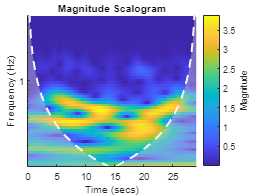

create_scalogram = true;
remove_existing_scalograms = true;
 step_window = 10;
 window = 30;

if create_scalogram
mkdir(dirPath+"/irisScalogram");
if remove_existing_scalograms
    delete(dirPath+"/irisScalogram/*.jpg");
end


for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;

    start_index = find(time==start_time);
    end_index = find(time==end_time);

    buildScalogram(irisResult.processed_position,time,[start_time,end_time]);
%     axis off;
% title("");
% colorbar off;
%     saveas(gcf,dirPath+"\irisScalogram\"+string(start_time)+"_"+string(end_time)+".jpg");

f=getframe; 
imwrite(f.cdata,...
dirPath+"\irisScalogram\"+string(start_time)+"_"+string(end_time)+".jpg");
end
end

### Save Scalograms with Exceedance

create_scalogram_exc = true;
remove_existing_scalograms_exc = true;
% step_window = 10;
% window = 30;

if create_scalogram_exc
mkdir(dirPath+"/irisScalogramWithExc");
if remove_existing_scalograms_exc
    delete(dirPath+"/irisScalogramWithExc/*.jpg");
end


for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;
    
    start_index = find(time==start_time);
    end_index = find(time==end_time);

    buildScalogram(irisResult.processed_position,time,[start_time,end_time]);
%     axis off;
%     title("");
%     colorbar off;
meanCurExc = mean(exceedance.rateExceedance(start_index : end_index))*10000;
%     saveas(gcf,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg")
f=getframe; 
imwrite(f.cdata,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg");
end
end

**Binary Alert/None Alert State**

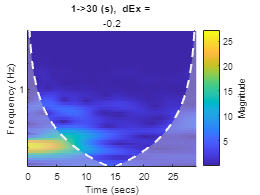

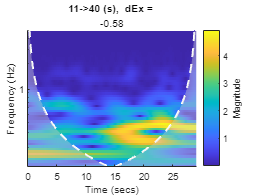

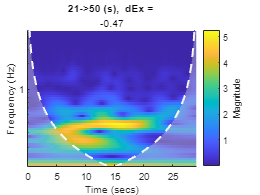

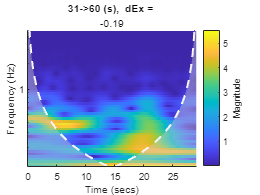

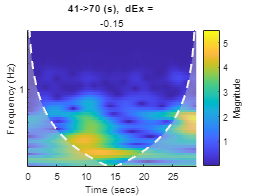

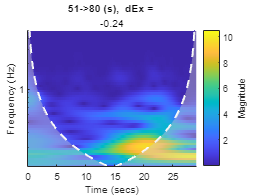

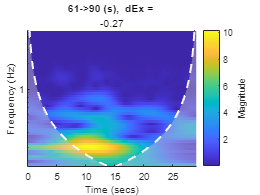

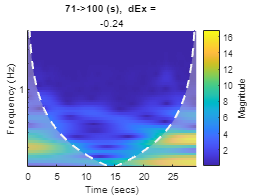

create_scalogram_exc_binary = true;
remove_existing_scalograms_exc_binary = true;
% step_window = 10;
% window = 30;
if create_scalogram_exc_binary
mkdir(dirPath+"/irisScalogramBinary");
mkdir(dirPath+"/irisScalogramBinary/0");
mkdir(dirPath+"/irisScalogramBinary/1");
if remove_existing_scalograms_exc_binary
    delete(dirPath+"/irisScalogramBinary/0/*.jpg");
    delete(dirPath+"/irisScalogramBinary/1/*.jpg");
end
%excGradNormalize = normalize(exceedanceResult.exceedanceGradient,'range',[-1,1]);
excGradNormalize = exceedance.rateExceedance;

for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;

    start_index = find(time==start_time);
    end_index = find(time==end_time);

excGradNormalize(start_time : end_time);
meanCurExcGradient = mean(excGradNormalize(start_index : end_index));
    figure;
     buildScalogram(irisResult.processed_position,time,[start_time,end_time])
        title(string(start_time)+"->"+string(end_time)+" (s), "+ " dEx = ",string(round(meanCurExcGradient,2)));

%     axis off;
%     title("");
%     colorbar off;


if(meanCurExcGradient<=excGradTreshhold)
    alertState=1;
    f=getframe; 
    imwrite(f.cdata,dirPath+"\irisScalogramBinary\1\"+string(int16(meanCurExcGradient*10000))+".jpg");
else 
    alertState=0;
    f=getframe; 
imwrite(f.cdata,dirPath+"\irisScalogramBinary\0\"+string(int16(meanCurExcGradient*1000))+".jpg");
end

   
%     saveas(gcf,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg")

end
end

Export te results and reports in to a PDF


%  export("autoExperimentAnalyzerV2.mlx",dirPath+"\"+pilotName_time,run=false,HideCode=true,PageSize="A4");

if(batchMode)
save(tempMatPath, 'output');
end



function [avg_peak_height, avg_return_time, signal_entropy] = analyze_exceedance(signal, time)
    % Find peaks
    [pks, locs] = findpeaks(signal);

    % Calculate the average peak height
    avg_peak_height = mean(pks);

    % Initialize variables for average return time calculation
    return_times = [];
    threshold = 0.4; % Return threshold (e.g., 5% of peak height)

    % Calculate the average time it takes for the signal to return to the threshold
    for i = 1:length(locs)
        peak_loc = locs(i);
        peak_value = pks(i);

        % Find the first point below the threshold after the peak
        below_threshold = find(signal(peak_loc:end) < peak_value * threshold, 1);

        if ~isempty(below_threshold)
            return_loc = peak_loc + below_threshold - 1;
            return_time = time(return_loc) - time(peak_loc);
            return_times = [return_times, return_time];
        end
    end

    avg_return_time = mean(return_times);

    % Calculate the entropy of the signal
    signal_entropy = entropy(signal);

    % Return relevant features in an array
end


